clc; clear all; close all; 

## Data Summary and Visualisation

### Working Directory

% Set working directory to the current directory 
addpath('src');
addpath("data/raw/")
setwdtocurrent()

### Import Data

Loading Sheet 1:

No0x2E2WT


Loading Sheet 2:

No0x2E3


Loading Sheet 3:

No0x2E14WT


Loading Sheet 4:

No0x2E39WT


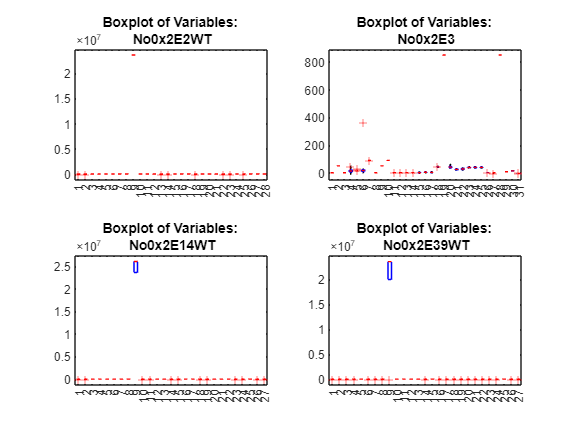

%Suppress warnings
warning('off');

% Define the Excel file name
excelFileName = 'data.xlsx';

% Get the sheet names from the Excel file
[~, sheetNames] = xlsfinfo(excelFileName);

% Loop through each sheet, read it into a table 
for i = 1:length(sheetNames)
    fprintf("Loading Sheet %d:", i)
    sheetName = sheetNames{i};
    % Generate a valid variable name in MATLAB
    tableName = genvarname(sheetName); 
    tableData = readtable(excelFileName, 'Sheet', sheetName, 'ReadVariableNames', true);
    % Save the table with the sheet name as the table name
    assignin('base', tableName, tableData);
    %Display the table name
    disp(tableName)

    % % Save the summary stats in an excel file
    currentDir = pwd;
    mainFolder = 'data';
    subFolder = 'processed';
    destinationFolder = fullfile(currentDir, mainFolder, subFolder);

    % Create the folder if it does not exist
    if ~exist(fullfile(currentDir, destinationFolder), 'dir')
        mkdir(fullfile(destinationFolder));
    end

    % Define the output file name
    outputFileName = fullfile(destinationFolder, 'summary.xls');
    
    % Write the table to Excel
    writetable(summarystats(eval(tableName)), outputFileName, 'Sheet', i);

    
    % Visualize the data in the table using boxplots
    folderName = 'images';

    % Create a folder named "images" if it does not exist
    if ~exist(fullfile(currentDir, folderName), 'dir')
        mkdir(fullfile(folderName));
    end
    subplot(2, 2, i)
    boxplot(table2array(eval(tableName)))
    title([sprintf('Boxplot of Variables: \n'), tableName])

    if i==length(sheetNames)
        saveas(gcf, fullfile('images', 'unscaledBoxplot.png'));
        % close(gcf); 
    end
end

## Data Pretreatment

### Discard the dataset for `WT3`

clear No0x2E3;

### Drop one of the columns in the dataset for `WT2`

No0x2E2WT = removevars(No0x2E2WT, "x28");

### Drop the observation with the missing value

No0x2E14WT = rmmissing(No0x2E14WT);

### Data centering and scaling

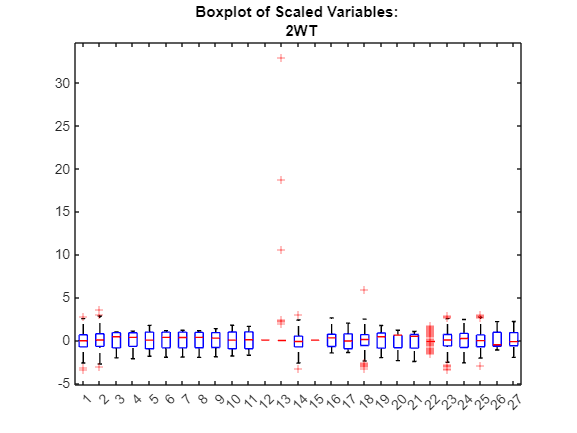

% % Center and scale the data for the healthy turbine
model(1).varNames = No0x2E2WT.Properties.VariableNames;

[model(1).No0x2E2WT, model(1).mu, model(1).sigma] = zscore(table2array(No0x2E2WT));

% Create a boxplot for the centered and scaled healthy turbine
figure;
boxplot(model(1).No0x2E2WT);
title(sprintf('Boxplot of Scaled Variables: \n 2WT'));

saveas(gcf, fullfile('images', 'No0x2E2Boxplot.png'));

model(1).No0x2E14WT

model = struct with fields:
      varNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'  'x22'  'x23'  'x24'  'x25'  'x26'  'x27'}
     No0x2E2WT: [1570×27 double]
            mu: [-0.0074 -0.0116 26.3116 29.2803 315.3096 41.0436 40.9062 41.0798 2.3575e+07 320.6220 1.3203e+03 1750 0.0110 -0.7541 849 223.6841 9.0433 685.0910 50.0023 17.6232 22.9118 10.7356 5.1643 5.4798 16.9228 53.2114 59.8223]
         sigma: [0.0455 0.0739 1.4622 1.6317 117.1357 2.2889 2.2389 2.2330 397.9615 117.0907 146.6609 0 0.0144 1.5969 0 15.4066 1.4409 2.1488 0.0454 0.3024 0.2864 0.2197 4.6742 0.7837 2.5627 3.1453 1.9001]
    No0x2E14WT: [685×27 double]


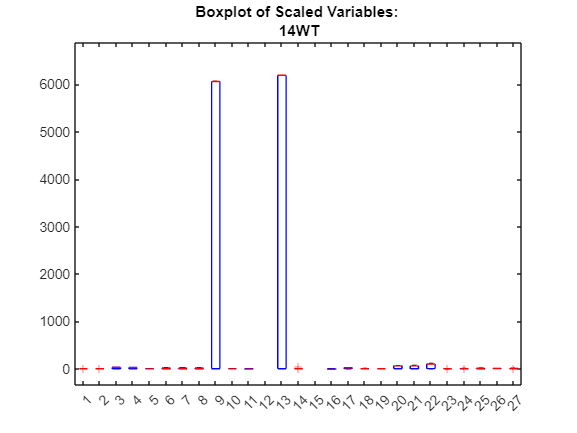

model(1).No0x2E39WT

model = struct with fields:
      varNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x12'  'x13'  'x14'  'x15'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'  'x22'  'x23'  'x24'  'x25'  'x26'  'x27'}
     No0x2E2WT: [1570×27 double]
            mu: [-0.0074 -0.0116 26.3116 29.2803 315.3096 41.0436 40.9062 41.0798 2.3575e+07 320.6220 1.3203e+03 1750 0.0110 -0.7541 849 223.6841 9.0433 685.0910 50.0023 17.6232 22.9118 10.7356 5.1643 5.4798 16.9228 53.2114 59.8223]
         sigma: [0.0455 0.0739 1.4622 1.6317 117.1357 2.2889 2.2389 2.2330 397.9615 117.0907 146.6609 0 0.0144 1.5969 0 15.4066 1.4409 2.1488 0.0454 0.3024 0.2864 0.2197 4.6742 0.7837 2.5627 3.1453 1.9001]
    No0x2E14WT: [685×27 double]
    No0x2E39WT: [1405×27 double]


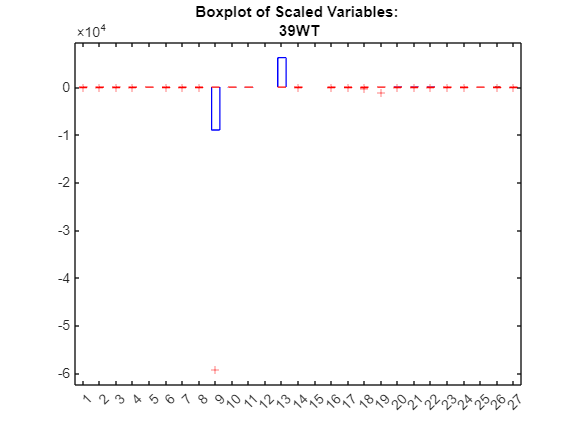


% %Apply the healthy turbine center and standard deviation to the faulty turbines
% Define the turbine numbers 
turbineNumbers = [14, 39];

% Create a loop to process each turbine
for i = 1:length(turbineNumbers)
    turbineNumber = turbineNumbers(i);
    
    % Access the corresponding windTurbine table
    windTurbine = evalin('base', sprintf('No0x2E%dWT', turbineNumber));
    
    % Normalize the data for the current turbine using the healthy turbine mean and standard deviation 
    fprintf(['model(1).' 'No0x2E' num2str(turbineNumber) 'WT'])
    model(1).(['No0x2E' num2str(turbineNumber) 'WT']) = normalize(table2array(windTurbine), 'Center', model(1).mu, 'Scale', model(1).sigma) 
    
    
    % Create a boxplot for the current turbine
    figure;
    boxplot(model(1).(['No0x2E' num2str(turbineNumber) 'WT']));
    title([sprintf('Boxplot of Scaled Variables: \n'), num2str(turbineNumber) 'WT'])

    saveas(gcf, fullfile('images', ['No0x2E' num2str(turbineNumber) 'Boxplot.png']));
    % close(gcf);
end

Functions

function summaryOutput = summarystats(data)
    dim = size(data);
    noOfVar = dim(2);
    summaryOutput = array2table(zeros(noOfVar, 5));
    summaryOutput.Properties.VariableNames = {'Mean','Std dev.', 'Max','Min', 'Median'};
    rowNames = data.Properties.VariableNames;
    summaryOutput.Properties.RowNames = rowNames;
    
    for i=1:noOfVar
        variable = data{:,i};
        summaryOutput{i,1} = mean(variable);
        summaryOutput{i,2} = std(variable);
        summaryOutput{i,3} = max(variable);
        summaryOutput{i,4} = min(variable);
        summaryOutput{i,5} = median(variable);

    end
end